# Analysis

## Import saved dataset

clear all;
% eeglab; close;
trials = {'001-AO', '002-AO', '003-AO'};

filepath = 'C:\\Users\\anhtn\\OneDrive - PennO365\\Documents\\GitHub\\analysis\\Datasets\\';

ALLEEG = cell(1,3);
for i=1:length(trials)
    filename = [trials{i} '-preprocessed.set']; % manually type to select dataset
    ALLEEG{i} = pop_loadset('filename', filename, 'filepath', filepath);
end

pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\001-AO-preprocessed.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\002-AO-preprocessed.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\003-AO-preprocessed.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...



trial_N = 2;
EEG = ALLEEG{trial_N};
plot_folder = ['plot-' trials(trial_N) '\\' ];

###  Parameters

chan_names = {'C3', 'C4'};
RH_cluster = {'C4', 'FC2', 'FC6', 'F4'};
LH_cluster = {'C3', 'FC5', 'FC1', 'F3'};
all_elec = [RH_cluster LH_cluster];
elec_plot = {all_elec}; % plot PSD of EEG at all relevant electrodes

theta_band = {4:8};
alpha_l_band = {8:10};
alpha_h_band = {10:13};
beta_band = {13:30};
freq_bands = [alpha_l_band, alpha_h_band, beta_band];

freqs_array = [4,8,13,30];

markerVal_string = ["10" "11" "12" "13" "14" "15" "16" "17"...
    "20" "21" "22" "23" "24" "25" "26" "27" ...
    "30" "31" "32" "33" "34" "35" "36" "37" ...
    "40" "41" "42" "43" "44" "45" "46" "47"];
markerVal_num = [10  11  12  13  14  15  16  17 20  21  22  23  24  25  26  27  30  31  32  33  34  35  36  37  40  41  42  43  44  45  46  47];
markerLabel = ["human-left", "human-right", "robot-left", "robot-right"];

actions_type1 = [3 4 5 6];
actions_type2 = [0 1 2 7];
actions = {actions_type1, actions_type2};

freqfac = 2;

## Baseline epochs and compute PSD of baseline

% base_tlen = [0 8];
% [spectra_base, freqs_base, specstd_base] = 
% cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
%         freqs_array, {{'C3', 'C4'}}, "", [], 'on');


### Checking correlation across 1sec time windows of full-epoch length baselin trials (n=12, t=8sec), using spectrogram (time-frequency decomposition)

%{
base_tlen = [0 8];
EEG_baseline = pop_select(EEG, 'channel', {'C3'});

figure();
EEG_base_window = pop_epoch(EEG_baseline, {'1000'}, base_tlen, 'verbose', 'off');
pop_newtimef(EEG_base_window, 1, 1, base_tlen*1000, [3 0.5], ...
                'freqs', [4 30], 'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', 'baseline', NaN);

spectrum_base_cell = cell(3,8);
for t = 1:8
    tlen = t-1:t;
    EEG_base_window = pop_epoch(EEG_baseline, {'1000'}, [tlen(1) tlen(end)], 'verbose', 'off');
    [ersp,~,~,times,freqs,~,~] = pop_newtimef(EEG_base_window, 1, 1, [tlen(1) tlen(end)]*1000, [3 0.5], ...
                'freqs', [4 30], 'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'off', 'verbose', 'off', 'baseline', NaN);

    for f = 1:3
        mean_ers = mean(ersp(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end), :));
        spectrum_base_cell{f,t} = mean_ers;
    end
end

newCell = cell(3, 1);
for i = 1:3
    % Concatenate along the second dimension to create a 7x21 matrix
    newCell{i} = cat(1, spectrum_base_cell{i, :})';
end
spectrum_base_cell = newCell;

for i = 1:3
    R = corrcoef(spectrum_base_cell{i})
end


*For subject 002, C3: Time window 4 and 5 have highest positive correlation, consistently >= 0.88 across all frequency bands.*

EEG_baseline = pop_select(EEG, 'channel', {'C4'});
figure();
EEG_base_window = pop_epoch(EEG_baseline, {'1000'}, base_tlen, 'verbose', 'off');
pop_newtimef(EEG_base_window, 1, 1, base_tlen*1000, [3 0.5], ...
                'freqs', [4 30], 'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', 'baseline', NaN);

spectrum_base_cell = cell(3,8);

for t = 1:8
    tlen = t-1:t;
    EEG_base_window = pop_epoch(EEG_baseline, {'1000'}, [tlen(1) tlen(end)], 'verbose', 'off');
    [ersp,~,~,times,freqs,~,~] = pop_newtimef(EEG_base_window, 1, 1, [tlen(1) tlen(end)]*1000, [3 0.5], ...
                'freqs', [4 30], 'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'off', 'verbose', 'off', 'baseline', NaN);

    for f = 1:3
        mean_ers = mean(ersp(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end), :));
        spectrum_base_cell{f,t} = mean_ers;
    end
end

newCell = cell(3, 1);
for i = 1:3
    % Concatenate along the second dimension to create a 7x21 matrix
    newCell{i} = cat(1, spectrum_base_cell{i, :})';
end
spectrum_base_cell = newCell;

for i = 1:3
    R = corrcoef(spectrum_base_cell{i})
end
%}

*For subject 2, C4: time window 2 and 4 have highest positive correlation (>= 0.8) across all freq bands.*

*=> Subject 2: Use time window 4 (3000-4000ms) for further analysis*

**SECTION TO BE REMOVED**

% EEG_baseline = pop_select(EEG, 'channel', {'C3','C4'});
% EEG_base_window = pop_epoch(EEG_baseline, {'1000'}, base_tlen, 'verbose', 'off');
% 
% ers_base = cell(1,2);
% figure(); %tiledlayout(2,1);
% for chan = 1:2
%     subplot(2,1,chan);
%     [ersp,~,~,times_base,freqs_base,~,~] = pop_newtimef(EEG_base_window, 1, chan, base_tlen*1000, [3 0.5], ...
%                     'freqs', [4 30], 'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', 'baseline', NaN, 'timesout', 50);
%     ers_base{chan} = ersp;
%     title(chan_names(chan))
% end

## Try out different correlation method: comparing PSD

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..
Plotting scalp distributions: ....
Click on each trace for channel/component index


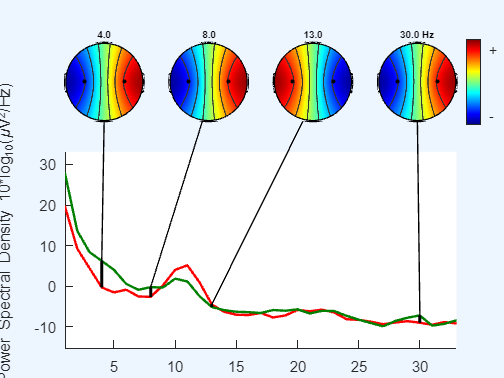

base_tlen = [0 8];
[spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3', 'C4'}}, "", [], 'on');



corrcoef_cell = [];
for t = 1:8
    tlen = t-1:t;
    EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3', 'C4'});
    [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
        'freq', freqs_array, 'plot', 'off', 'verbose', 'off');
    R = 0;
    for f = 1:3
        for chan = 1:2
            spectra_band = spectra(chan, freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
            spectra_base_band = spectra_base(chan, freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
    end
    R = R/(3*2);
    corrcoef_cell = [corrcoef_cell R];
end

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..


corrcoef_cell

corrcoef_cell =     0.6139    0.8712    0.8333    0.8277    0.8665    0.8858    0.8727    0.8798


[~, idx_base] = max(corrcoef_cell)

idx_base = 6

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..
Plotting scalp distributions: ....
Click on each trace for channel/component index


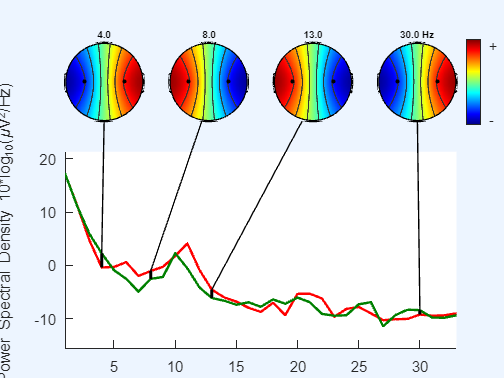


base_tlen = [idx_base-1 idx_base];
[spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3', 'C4'}}, "", [], 'on');


spectra_base_abs = 10.^(spectra_base./10);

**Time window 2 (1000-2000ms) has the highest correlation (averaged across 3 bands) with the spectra (PSD) averaged across all baseline (8sec) epochs.**

**Use this time window for further analysis**

EEG_cond_epoch = cond_epoch(EEG, {'1000'}, base_tlen);

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3', 'C4'});

Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


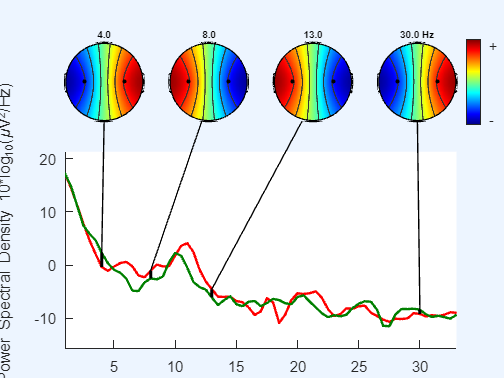

pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
..
Plotting scalp distributions: ....
Click on each trace for channel/component index


figure();
pop_spectopo(EEG_cond_chan, 1, [base_tlen(1) base_tlen(end)]*1000, 'EEG',...
    'freq', freqs_array, 'plot', 'on', 'verbose', 'off', 'freqfac', 2);

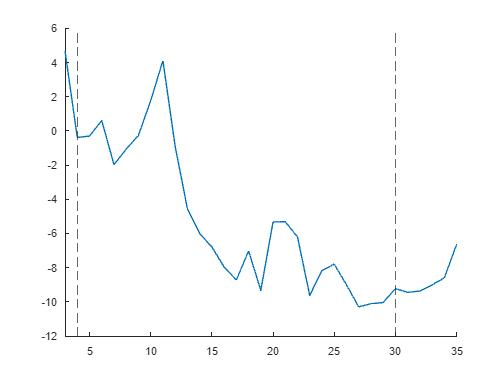


figure(); hold on
plot(freqs_base, spectra_base(1,:))
% plot(freqs_base, spectra_base(2,:))
xline([4 30], '--')
xlim([3 35])
hold off

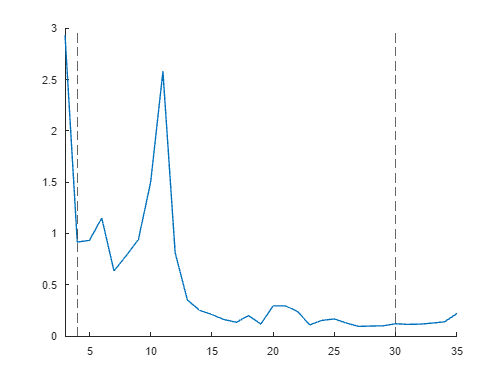


figure(); hold on
plot(freqs_base, spectra_base_abs(1,:))
% plot(freqs_base, spectra_base_abs(2,:))
xline([4 30], '--'); xlim([3 35])
hold off

base_tlen = [5 7];
[spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, "", [], 'off');

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 5000.00 ms to 7000.00 ms (points 1 to 256)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
.



spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
spectra_base_abs = 10.^(spectra_base./10);


% epoching 
EEG_cond_epoch = pop_epoch(EEG, {'1000'}, base_tlen);

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});

Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


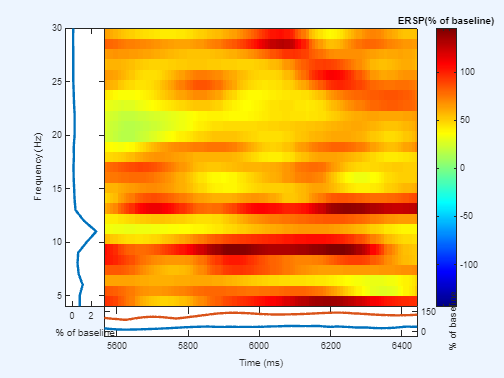

Value of timesout must be <= frames-winsize, timeout adjusted to 224



figure();
% Compute event-related spectrogram (ERS)
[ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
     pop_newtimef(EEG_cond_chan, 1, 1, base_tlen*1000, [4 15.36], ...
                'freqs', [4 30],'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', ...
                'powbase', spectra_base_abs, 'scale', 'abs', 'timesout', 400);

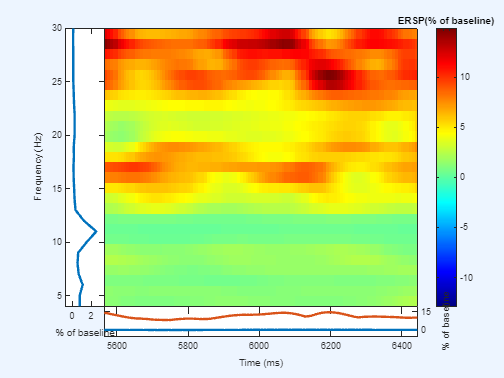

Value of timesout must be <= frames-winsize, timeout adjusted to 224


figure();
% Compute event-related spectrogram (ERS)
[ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
     pop_newtimef(EEG_cond_chan, 1, 1, base_tlen*1000, [4 15.36], ...
                'freqs', [4 30],'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', ...
                'powbase', spectra_base_abs, 'trialbase', 'full', 'scale', 'abs', 'timesout', 400);

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 7000.00 ms (points 1 to 256)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


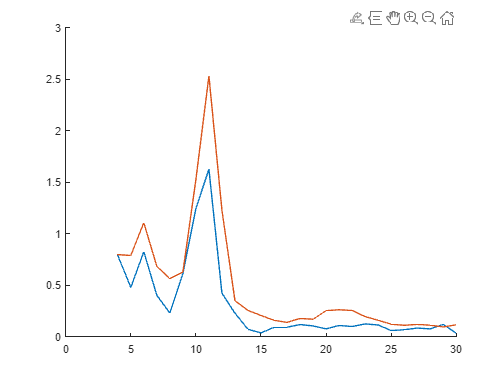


% % Baseline correction
% erspec = zeros(size(ersp));
% for row = 1:height(ersp)
%     erspec(row, :) = ersp(row, :) / spectra_base_abs(1, freqs == freqs(row));
% end
% erspec = 10.*log10(erspec);
% 
% figure(); sgtitle('Absolute power ratio wrt baseline activity (baseline - baseline)')
% imagesc(times, freqs, erspec);
% xline([1000 3000], '--');
% yline([4 8 13 15 20], '--', 'Color', 'magenta')
% axis xy; colormap(jet(256)); colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');


## Stim epochs

### Plot power spectrum density of conditions

% stim_epoch = [0 4];
% figure(); 
% for i = 1:4
%     events_cell = num2cell(markerVal_num((i-1)*8+1:i*8));
%     tlen = stim_epoch;
%     plottitle = [];
%     EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
% 
% 
%     EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3', 'C4'});
%     subplot(2,2,i); title(plottitle);
%     [spectra,freqs,speccomp,contrib,specstd] = pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG',...
%         'freq', freqs_array, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', 'on', 'verbose', 'off');
% end


### Compute Spectrogram of the stim epoch: time-frequency transform (using newtimef with option 'Baseline' being NaN)

Angelini 2018

base_tlen = [idx_base-1 idx_base];
[spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, "", [], 'off');

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
.


spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
spectra_base_abs = 10.^(spectra_base./10);

figure(); hold on
plot(4:30, spectra_base + 10*log10(128/2))

stim_tlen = [0 4];
for i=1:4
    [spectra_stim, freqs_stim, ~] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
            freqs_array, {{'C3'}}, "", [], 'off');
    spectra_stim = spectra_stim(freqs_stim >= 4 & freqs_stim <= 30);
    spectra_stim_abs = 10.^(spectra_stim./10);
    
    plot(4:30, spectra_stim+ 10*log10(128/2))
end

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00

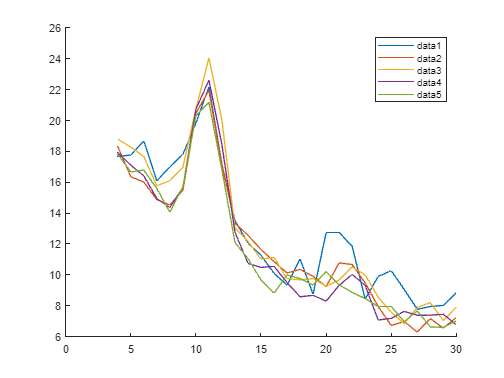

hold off; legend()

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


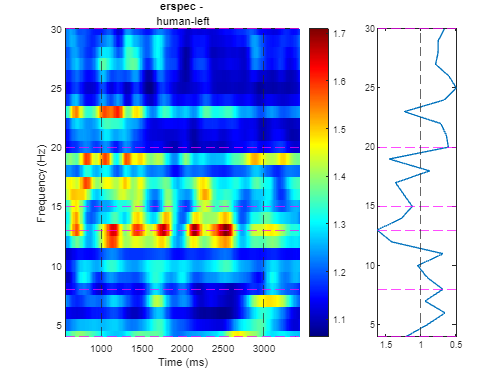

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


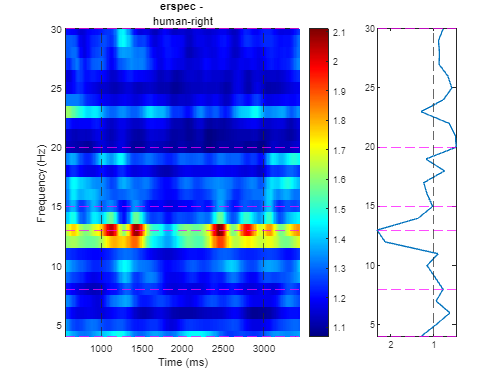

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


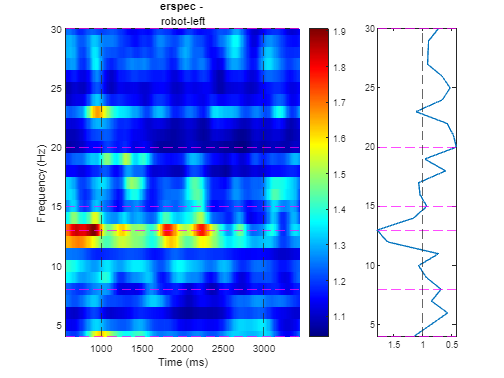

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


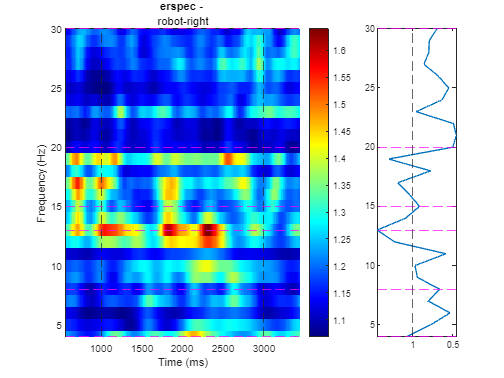



stim_tlen = [0 4];
for i=1:4
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
    % figure(); title('stim')
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
        pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
        'freqs', [4 30],'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'off', ...
        'verbose', 'off', 'baseline', NaN);
    
    % Baseline correction
    erspec = zeros(size(ersp));
    for row = 1:height(ersp)
        erspec(row, :) = ersp(row, :) - (spectra_base(row) + 10*log10(128/2));
    end
    erspec = 10.^(erspec/10);
    erspec_mean = mean(erspec, 2);
    figure();
    subplot(1,4,1:3); hold on
    imagesc(times, freqs, 10.^(erspec/10)); box on
    xline([1000 3000], '--');
    yline([4 8 13 15 20 30], '--', 'Color', 'magenta')
    axis xy; colormap(jet(256)); colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    ylim([4 30]); xlim([min(times) max(times)]);
    title('erspec - ', markerLabel(i))
    hold off
    subplot(1,4,4); hold on
    plot(erspec_mean, freqs)
    yline([4 8 13 15 20 30], '--', 'Color', 'magenta'); xline(1, '--')
    ylim([4 30])
    set ( gca, 'xdir', 'reverse' ); box on
    hold off
end

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


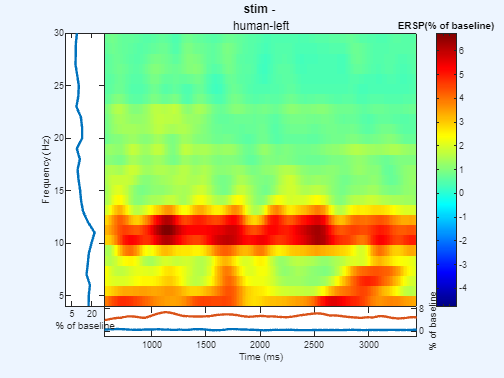

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


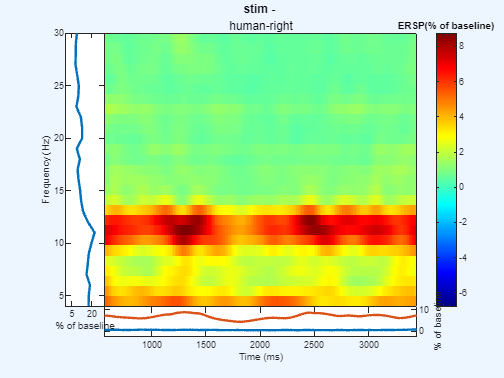

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


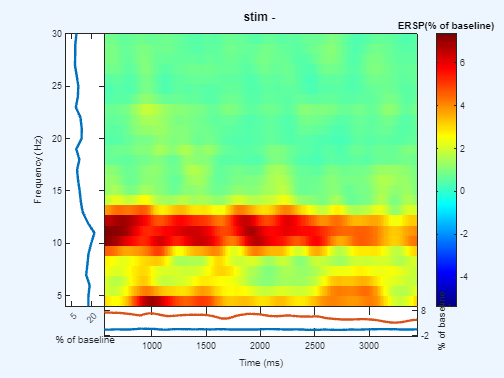

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


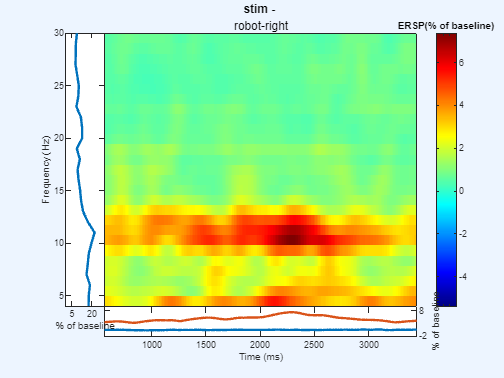

base_tlen = [5 7];
EEG_cond_epoch = pop_epoch(EEG, {'1000'}, base_tlen);
EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
figure(); title('baseline')
[ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
    pop_newtimef(EEG_cond_chan, 1, 1, base_tlen*1000, [4 15.36], ...
    'freqs', [4 30],'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', ...
    'baseline', NaN);

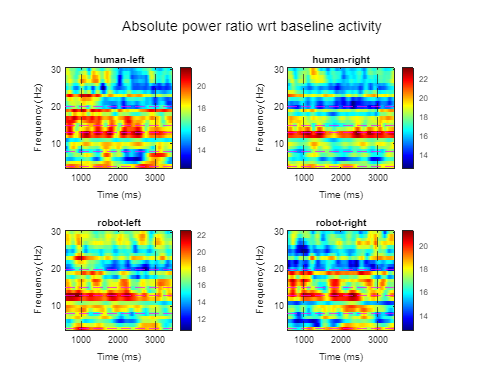

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...



stim_tlen = [0 4];
figure(); sgtitle('Absolute power ratio wrt baseline activity')
for i=1:4
    % epoching 
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
    
    % Compute event-related spectrogram (ERS)
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
         pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
                    'freqs', [4 30],'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'off', 'verbose', 'off', ...
                    'baseline', NaN);
    
    % Baseline correction
    erspec = zeros(size(ersp));
    for row = 1:height(ersp)
        erspec(row, :) = ersp(row, :) - spectra_base(row);
    end
    subplot(2,2,i);
    imagesc(times, freqs, erspec);
    xline([1000 3000], '--');
    yline([4 8 13 15 20], '--', 'Color', 'magenta')
    axis xy; colormap(jet(256)); colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    title(markerLabel(i));
end

stim_tlen = [0 4];
figure(); sgtitle('Absolute power ratio wrt baseline activity')
for i=1:4
    % epoching 
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C4'});
    
    % Compute event-related spectrogram (ERS)
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
         pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
                    'freqs', [4 30],'nfreqs', 27, 'plotitc', 'off', 'plotersp', 'off', 'verbose', 'off', ...
                    'baseline', NaN, 'trialbase', 'full', 'scale', 'abs', 'timesout', 400);
    
    % Baseline correction
    erspec = zeros(size(ersp));
    for row = 1:height(ersp)
        erspec(row, :) = ersp(row, :) / spectra_base_abs(2, freqs_base == freqs(row));
    end
    subplot(2,2,i);
    imagesc(times, freqs, erspec);
    xline([1000 3000], '--');
    yline([4 8 13 15 20], '--', 'Color', 'magenta')
    axis xy; colormap(jet(256)); colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    title(markerLabel(i));
end

figure();
for i=1:4
    % epoching 
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
    
    % Compute event-related spectrogram (ERS)
    subplot(2,2,i)
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
         pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
                    'freqs', [4 30], 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', ...
                    'baseline', NaN, 'scale', 'abs');
end

figure();
for i=1:4
    % epoching 
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
    
    % Compute event-related spectrogram (ERS)
    subplot(2,2,i)
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
         pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
                    'freqs', [4 30], 'plotitc', 'off', 'plotersp', 'on', 'verbose', 'off', ...
                    'baseline', NaN, 'trialbase', 'full', 'scale', 'abs');
end

function [ersp_out, times, freqs_out, erspboot_out ] = cond_ersp(EEG, events_cell, tlen, sub_epoch_len, freqs, channels, erspmax, alpha, plottitle, filepath, toPlot)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    if length(channels) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', channels);
        if alpha ~= 0
            if string(toPlot) == "off"
                [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            else
                figure;
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            end
            else
            figure; 
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot,'erspmax', erspmax, 'verbose', 'off');
        end
    
    elseif length(channels) == 2
        EEG_cond_chan1 = pop_select( EEG_cond_epoch, 'channel', channels(1));
        EEG_cond_chan2 = pop_select( EEG_cond_epoch, 'channel', channels(2));

        if alpha ~= 0
            if string(toPlot) == "off"
                [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
                [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            else

            figure; sgtitle(plottitle)
            subplot(2,1,1); 
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2); 
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(2)))
            end
        else 
            if string(toPlot) == "off"
                [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
                [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            else

            figure; sgtitle(plottitle)
            subplot(2,1,1); 
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2); 
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(2)))
            end
        end
        save_figures(filepath, plottitle, toPlot)
        ersp_out = {ersp1, ersp2}; erspboot_out = {erspboot1, erspboot2};
    end

end
%=================================================================
% function 

% ===================================================
function [spectra,freqs,specstd] = cond_plot_spectra(EEG, events_cell, tlen, freqs, chanlocs, plottitle, filepath, toPlot)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    
    if length(chanlocs) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', chanlocs{1});
        if string(toPlot) == "on"
            figure; title(plottitle);
        end
        [spectra,freqs,speccomp,contrib,specstd] = pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');

    elseif length(chanlocs) == 2
        EEG_cond_RH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1});
        EEG_cond_LH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1}); 
        figure; sgtitle(plottitle);
        subplot(211); 
        pop_spectopo(EEG_cond_RH, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
        subplot(212); 
        pop_spectopo(EEG_cond_LH, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
    end
    % save_figures(filepath, plottitle, toPlot)
end


%===================================================
function OUTEEG = cond_epoch(EEG, events_cell, tlen)
    % events_cell
    EEG_epoch = pop_epoch(EEG, events_cell, tlen, 'verbose', 'off');
    OUTEEG = pop_rmbase(EEG_epoch, [0 0.5]*1000);

end


function save_figures(filepath, plottitle, toPlot)
    if string(toPlot) == "on"
        savefig(fullfile(filepath, plottitle+".fig"));
        saveas(gcf, fullfile(filepath, plottitle+".png")) 
    end
end


%=================================================================
function plot_ersp_band(times, mean_ersp_bands, std_ersp_bands, cond_num, band_colors, band_names, chan_name)
    hold on;
    xline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
    yline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
    for i = 1:length(mean_ersp_bands)
        plot(times, mean_ersp_bands{1,i}, 'Color', band_colors(i), 'DisplayName', band_names(i))
        fill([times, fliplr(times)], [mean_ersp_bands{1,i} + std_ersp_bands{1,i}, ...
            fliplr(mean_ersp_bands{1,i} - std_ersp_bands{1,i})], band_colors(i), 'EdgeColor', 'none', ...
            'FaceAlpha', 0.2, 'HandleVisibility', 'off');
    end
    if cond_num == 1
        title(chan_name); 
    end
    xlim([min(times), max(times)]);
    ylabel('ERDS (dB)'); xlabel('time [ms]')
    hold off;
end













